# Homework 10 Problem 13.1

clear; close; clc;


## Inexact stepsize test

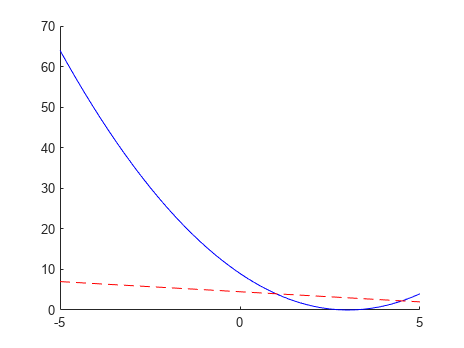

figure; 
hold on; 
x_0 = 1; 
fplot(@(x)(x-3).^2,"-b"); 
fplot(@(x) (x_0-3).^2-.5*(x-x_0),"--r"); 

x_0 + inexactStepSize(1, 1, @(x) (x-2)^2, .5, .5)

ans = 2

## Declaration and Initialization

% solver parameters
epsilon_1 = 1e-6; % unconstrained tolerance
epsilon_2 = 1e-6; % near constraint tolerance
R = 1; % initial value for penalty parameter
gamma = .5; % parameter for inexact line search (range [0,1])
mu = .5;
max_iterations = 10000; % maximum number of itterations until program termination
H = eye(2); % Hessian to be used in quadratic subproblem (set to Identity for CSD)

% initial condition
x = [250; 300]; % initial values for b and d repsectively
%x = [450; 800];

% constraints

% loop vairables
k = 0; % itteration number


% Matrices to store values
x_hist = zeros([length(x), max_iterations]); % design variable values
d_hist = zeros([length(x), max_iterations]); % step sizes
f_hist = zeros([1, max_iterations]); % function values
alpha_hist = zeros([1, max_iterations]); % step sizes
R_hist = zeros([1, max_iterations]); % Penalty parameters

% TODO store initial values

## Optimizer


% CSD algorithm:
%   obtain quadratic subproblem f_tilde = c.T d + 1/2 d.T d
%   solve quadriatic subproblem -> alpha, LM
%   obtain descent function
%   minimize descent function -> step size
%   update design


% what I will do:

% find important vlaues @ current x ( c, g, grad(g), h, grad(h), v )
% solve QP subproblem
% check convergence
% Select R_next
% solve step size (inexact line search)
% update design

options = optimoptions('quadprog', 'Display', 'off'); % prepare options for quadprog

g= Inf; % initialize g to inf to ensure first itteration of loop runs 

while k < max_iterations && (any(g > epsilon_1) || norm(d) > epsilon_2)
    % find important vlaues @ current x ( c, g, grad(g), h, grad(h), v )
    [f, c] = objective_Function(x); % cost func vlaue and cost fun gradient
    [g, A] = inequalConstraintFunction(x); % ineqality contraint value and inequality contraint gradient
    
    % store values of variables
    x_hist(:,k+1) = x;
    f_hist(k+1) = f;

    % solve QP sub prooblem
    % Takes:  function handle, cost; function handle equlaity constraints; function handle inequlaity constraints
    % use quad prog
    b = -g; % negative contraint values
    [d, ~, exitflag, ~, lambda] = quadprog(H, c, A, b, [], [], [], [], [], options); % solves the quadratic progrmming problem at design point using provided values of hessian, cost gradient, contraint gradient matrix, and negative contraint values

%     disp("is descent direction: " +(dot(c,d)<=0))
%     disp("is current point feasible: " +all(g>=epsilon_1))

    % check that convergence was obtained
    if exitflag ~= 1 % did solution converge?
        % alert user and fail gracefully
        error("Quadratic subproblem failued to converge on itteration %g. exit flag: %g", k, exitflag);
    end

    if norm(d) <= epsilon_2 % within to of opt
        break
    end

    
    % lagrange multipiers of solution
    v = lambda.eqlin; % linear equality contraint lagrange multipliers -> rewrite to include if relevant
    u = lambda.ineqlin; % linear inequality contraint lagrange multipliers
    
    % compute descent function:
    [phi, R] = DescentFunction(x, R, @(x)inequalConstraintFunction(x), @(x)objective_Function(x), u, v);
    
    % solve step size:
    alpha = inexactStepSize(x, d, phi, gamma, mu);
    %alpha = golden_search(phi, x, d, 1e-5);
    %alpha = 1

    % print output
%     k
%     x
%     f
%     R
%     d
%     alpha

    % update design
    x = x + alpha*d;
    k = k+1;

    % updates stored variables
    d_hist(:,k+1) = d;
    alpha_hist(k+1) = alpha;
    
end
disp("done")

done



%figure
%plot(x_hist)

## Plot


% Create a grid of points
xSpace = linspace(0, 400, 400);
ySpace = linspace(0, 400, 400);
[X, Y] = meshgrid(xSpace, ySpace);

% Evaluate the objective function on the grid
Z = X .* Y;

% Define the functions
g1 = @(x, y) 2.4e8 ./ (x .* y.^2) - 10;
g2 = @(x, y) 4.5e5 / (2 * x * y) - 2;
g3 = @(x, y) y - 2 * x;


figure;
%%Create two axes
ax1 = axes;
% plot f
contourf(X, Y, Z, 50);
hold on
% Plot g1
fimplicit(@(x, y) g1(x, y), [0, 400, 0, 400], 'r', "LineWidth",2);

% Plot g2
fimplicit(@(x, y) g2(x, y), [0, 400, 0, 400], 'g', "LineWidth",2);


% Plot g3
fimplicit(@(x, y) g3(x, y), [0, 400, 0, 400], 'b', "LineWidth",2);

% Add labels and title
xlabel('x');
ylabel('y');
title('Implicit Plots of g1, g2, and g3');
legend('f','g1', 'g2', 'g3','convergence history');

grid on;
view(2)
ax2 = axes;
patch([x_hist(1,1:k), nan], [x_hist(2,1:k), nan], [1:k, nan], 'EdgeColor', 'interp', 'Marker', 'o', 'MarkerFaceColor', 'flat', 'LineWidth', 2, 'FaceColor', 'none');


%%Link them together
linkaxes([ax1,ax2])

%%Hide the top axes
ax2.Visible = 'off';
ax2.XTick = [];
ax2.YTick = [];
%%Give each one its own colormap
colormap(ax1,'cool')
colormap(ax2,flipud(hot))
%%Then add colorbars and get everything lined up
set([ax1,ax2],'Position',[.17 .11 .685 .815]);
cb1 = colorbar(ax1,'Position',[.05 .11 .0675 .815]);
cb2 = colorbar(ax2,'Position',[.88 .11 .0675 .815]);

function [f, c] = objective_Function(x)
    f = x(1).*x(2)/100; % cost function
    c = [x(2,:), x(1,:)]/100; % const function gradient
end

function [g, A] = inequalConstraintFunction(x)
    g = zeros([3,1]); % initialize g

    % assign values to constraints
    g(1) = 2.4e8 / ( x(1) * x(2)^2 ) - 10;
    g(2) = 4.5e5 / ( 2 * x(1) * x(2)) - 2;
    g(3) = x(2) - 2*x(1); % this contraint may need to be normalized (mult by .5)

    

    % compute gradient of contraints
    A = [
        -2.4e8 / (x(1)^2 * x(2)^2)  , -4.8e8 / (2 *x(1) * x(2)^3) ; % partials of g_1
        -4.5e5 / (2*x(1)^2 * x(2))  , -4.5e5 / (2*x(1) * x(2)^2)  ; % partials of g_2
        -2                          , 1                             % partials of g_3
        ];

    % normalized
    % assign values to constraints
%     g(1) = (2.4e8 / ( x(1) * x(2)^2 ) - 10)/10;
%     g(2) = (4.5e5 / ( 2 * x(1) * x(2)) - 2) *10;
%     g(3) = (x(2) - 2*x(1))/200; % this contraint may need to be normalized (mult by .5)
%     % compute gradient of contraints
%     A = [
%         -2.4e8 / (x(1)^2 * x(2)^2) / 10  , -4.8e8 / (2 *x(1) * x(2)^3) / 10 ; % partials of g_1
%         -4.5e5 / (2*x(1)^2 * x(2)) *10  , -4.5e5 / (2*x(1) * x(2)^2) *10 ; % partials of g_2
%         -2/200                          , 1/200                             % partials of g_3
%         ];

end